# Práctica 4 - Métodos numéricos

#### Ejemplo 5 - Euler

% Ecuación diferencial
f = @(t, P) 4 / 7 * P - P^2 / 7000 - 200 * (1 + sin(t));
a = 0; b = 20;
n = 50; 
h = (b - a) / n;
T = a : h : b;

% Condición inicial
P(1) = 1000;

% Aplicamos el método de Euler (explícito)
for i = 1 : n
    P(i + 1) = P(i) + h * f(T(i), P(i)); 
end

% Valor aproximado de la última instancia temporal
P_20 = P(n + 1) 

P_20 =      3.635736761996473e+03


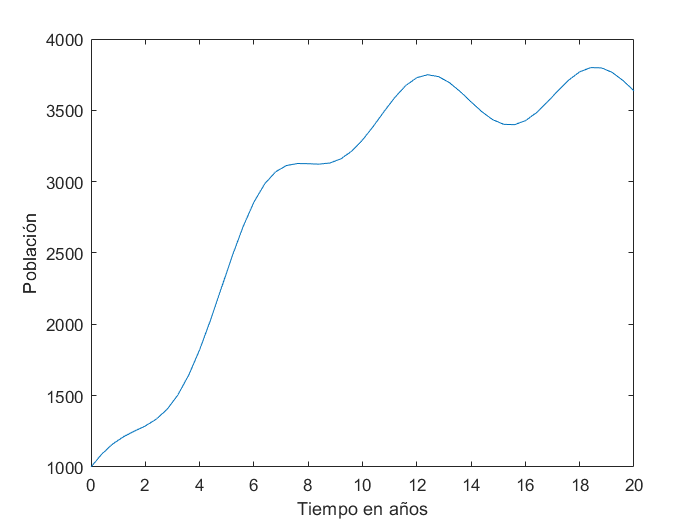


% Representación
figure, plot(T, P)
xlabel('Tiempo en años'), ylabel('Población')

#### Ejemplo 10 - Runge Kutta de orden 4 (RK4)

clear
f = @(t,P) 4/7*P-P^2/7000-200*(1+sin(t));
[T,P]=ode45(f, [0, 20], 1000);
ultimo=length(P)

ultimo =     45


format long, P_runge=P(ultimo) 

P_runge =      3.603903837629960e+03


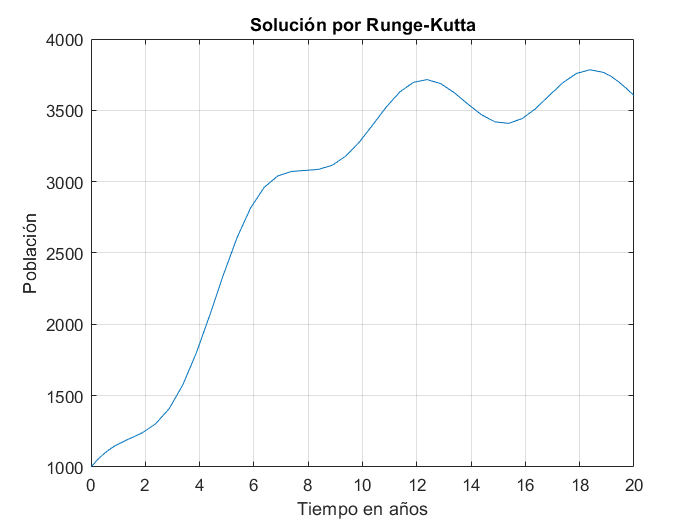


% Representación
plot(T,P),grid
xlabel('Tiempo en años'),ylabel('Población'),title('Solución por Runge-Kutta') 

#### Ejemplo 12 - Evolución de un cáncer

clear
F = @(t, y)[
16*sqrt(3)*y(1)+y(1)*y(2)*(y(1)-16)-2*sqrt(3)*y(1)^2;
0.5*y(1)^2*y(2)-4*y(1)*y(2)+y(2)^2*(2*sqrt(3)-0.5*y(2))];
[T, Y] = ode45(F, [0, 2], [0.6, 2.7]);

ultimo = length(Y);
Y(ultimo, :) 

ans =    0.000000060744852   6.928203258741076


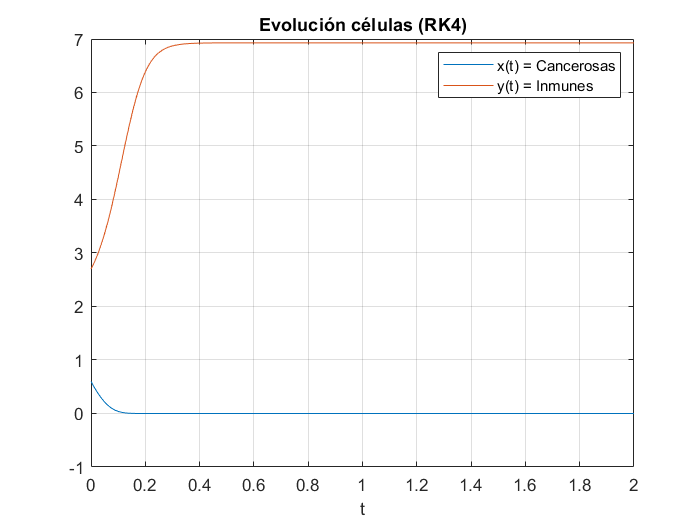


% Representación
plot(T, Y), grid, legend('x(t) = Cancerosas','y(t) = Inmunes')
xlabel('t');
title('Evolución células (RK4)')